% Test Zone

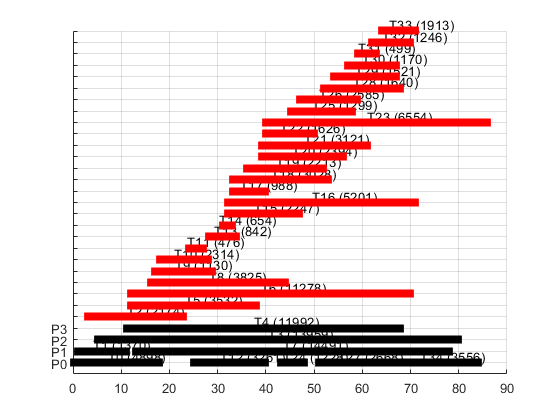

% Tabela de tasks

clear all
str = convertStringsToChars(splitlines(extractFileText('tasks_35_04_0.txt')));
profits = str2double(splitlines(extractFileText('profits_35_04_0.txt')));
progs={};
prog={};
tasks={};
for p=1:(length(str)-1)
    if(str{p}(1)=='P')
        progs{p} = split(str(p));
        final = p;
    else
        tasks{(p-(final))}=split(str(p));
    end
end
margem = p*2/100;

figure(1)

%prints
close all
hold on
for  i= 1:final
    for k=3:3:(length(progs{i})-1)
        t=(str2double(progs{i}{k-1}):str2double(progs{i}{k+1}));
        p=ones(1,length(t));
        title = progs{i}{k};
        fim = length(regexp(title,'[0-9]'))+1;
        if fim ==2
            iprofit = str2num(title(2))+1;
        else
            iprofit = str2num(title(2:fim))+1;
        end
        if(profits(iprofit)~=1)
            txt = [progs{i}{k},' (',int2str(profits(iprofit)),')'];
            avg =(t(1)+(t(end)-t(1))/2)-length(txt)/5;
        else
            txt = title;
            avg =(t(1)+(t(end)-t(1))/2)-0.3;
        end
        text(avg,i+margem,txt);
        prog{i} = char(progs{i}(1));
        plot(t, i*p, 'k-|',"LineWidth",5);
    end   
end

for q=1:length(tasks)
    t=(str2double(tasks{q}{1}):str2double(tasks{q}{3}));
    p=ones(1,length(t));
    title = tasks{q}{2};
    fim = length(regexp(title,'[0-9]'))+1;
    iprofit = str2num(title(2:fim))+1;
    if(profits(iprofit)~=1)
        txt = [tasks{q}{2},' (',int2str(profits(iprofit)),')'];
        avg =(t(1)+(t(end)-t(1))/2)-length(txt)/5;
    else
        txt = title;
        avg =(t(1)+(t(end)-t(1))/2)-0.3;
    end
    text(avg,((q+final)+margem),txt);
    plot(t, (q+final)*p, 'r-|',"LineWidth",5);
    prog{q+final} = char('');
end
hold off
grid;
ay = gca;
ay.YTickLabel = prog;
yticks(1:length(prog));

% Results
